clear; clc; close all;

fmt = @(x) round(x,4);

old_h = [11,15,19,22,24,27,28,30,31,33,35,36,37,38,39,42,43,46,49,64];
new_h = [16,21,25,27,32,34,35,36,40,41,43,44,47,48,49,50,52,54,55,61];

old_n = numel(old_h);
old_mean = mean(old_h);
old_std = std(old_h);
old_median = median(old_h);
old_var = var(old_h);
old_se = old_std / sqrt(old_n);
old_CV = old_std / old_mean * 100;
old_kurt = kurtosis(old_h) - 3;
old_skew = skewness(old_h);
old_min = min(old_h);
old_max = max(old_h);
old_range = range(old_h);
old_sum = sum(old_h);

% Quartiles, IQR, and outlier bounds for old_h
old_Q1 = prctile(old_h, 25);
old_Q2 = prctile(old_h, 50);
old_Q3 = prctile(old_h, 75);
old_IQR = old_Q3 - old_Q1; 

old_lower_bound = old_Q1 - 1.5 * old_IQR;
old_upper_bound = old_Q3 + 1.5 * old_IQR;

%----------------------------------------------------

new_n = numel(new_h);
new_mean = mean(new_h);
new_std = std(new_h);
new_median = median(new_h);
new_var = var(new_h);
new_se = new_std / sqrt(new_n);
new_CV = new_std / new_mean * 100;
new_kurt = kurtosis(new_h) - 3;
new_skew = skewness(new_h);
new_min = min(new_h);
new_max = max(new_h);
new_range = range(new_h);
new_sum = sum(new_h);

% Quartiles, IQR, and outlier bounds for new_h
new_Q1 = prctile(new_h, 25);
new_Q2 = prctile(new_h, 50);
new_Q3 = prctile(new_h, 75);
new_IQR = new_Q3 - new_Q1;
new_lower_bound = new_Q1 - 1.5 * new_IQR;
new_upper_bound = new_Q3 + 1.5 * new_IQR;


%----------------------------------------------------

row_names = {'Sample size','Mean','Std Error','Median','Std Dev','Variance', ...
    'CV(%)', 'Kurtosis', 'Skewness', 'Min','Max','Range','Sum', 'Q1', 'Q2 (median)', 'Q3', 'IQR', 'Lower Bound', 'Upper Bound'};

old_stats = [old_n; old_mean; old_se; old_median; old_std; old_var; old_CV; ...
    old_kurt; old_skew; old_min; old_max; old_range; old_sum; old_Q1; old_Q2; ...
    old_Q3; old_IQR; old_lower_bound; old_upper_bound];

new_stats = [new_n; new_mean; new_se; new_median; new_std; new_var; new_CV; ...
    new_kurt; new_skew; new_min; new_max; new_range; new_sum; new_Q1; new_Q2; ...
    new_Q3; new_IQR; new_lower_bound; new_upper_bound];

descriptive_stats = array2table([fmt(old_stats) fmt(new_stats)], ...
    'VariableNames', {'Old (h)','New (h)'}, ...
    'RowNames', row_names);

disp('--- DESCRIPTIVE STATISTICS ---');

--- DESCRIPTIVE STATISTICS ---


disp(descriptive_stats);

                   Old (h)    New (h)
                   _______    _______

    Sample size        20          20
    Mean            33.45        40.5
    Std Error      2.7782      2.7111
    Median             34          42
    Std Dev        12.424      12.124
    Variance       154.37         147
    CV(%)          37.143      29.937
    Kurtosis       0.2806     -0.7075
    Skewness       0.3556     -0.3508
    Min                11          16
    Max                64          61
    Range              53          45
    Sum               669         810
    Q1               25.5          33
    Q2 (median)        34          42
    Q3               40.5        49.5
    IQR                15        16.5
    Lower Bound         3        8.25
    Upper Bound        63       74.25



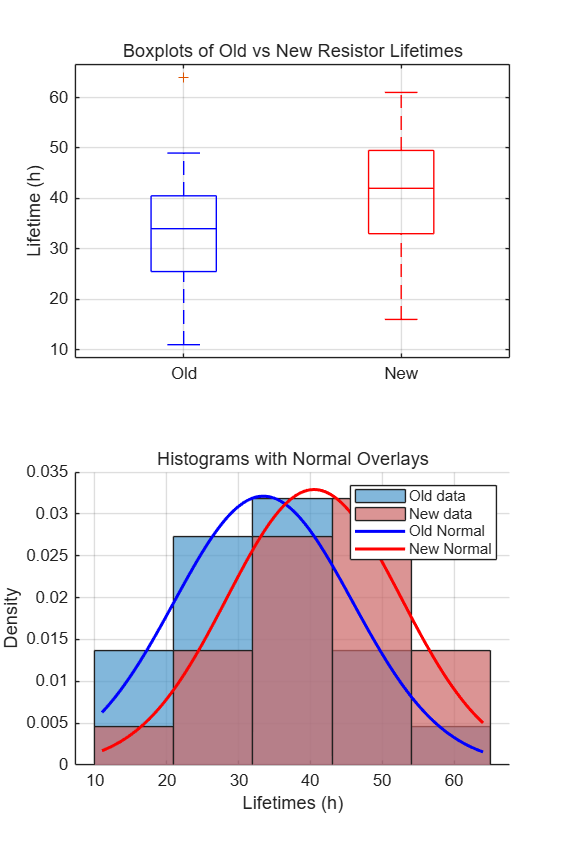

figure('Color','w','Position',[100 100 980 1500]);

% ---- Boxplots ----
subplot(2,1,1);
boxplot([old_h'; new_h'], ...
    [repmat({'Old'}, old_n, 1); repmat({'New'}, new_n, 1)], ...
    'Colors', ['b','r']);
title('Boxplots of Old vs New Resistor Lifetimes');
ylabel('Lifetime (h)');
grid on;

% ---- Histograms + normal overlays ----
subplot(2,1,2); hold on;
k = round(1 + 3.322 * log10(old_n)); % Sturges' bin rule
[observed_freq, edges] = histcounts([old_h new_h], k);
histogram(old_h, 'BinEdges', edges, 'Normalization','pdf', 'FaceColor',[0.3 0.6 0.8], 'FaceAlpha',0.7);
histogram(new_h, 'BinEdges', edges, 'Normalization','pdf', 'FaceColor',[0.8 0.4 0.4], 'FaceAlpha',0.7);
x = linspace(min([old_h new_h]), max([old_h new_h]), 300);
plot(x, normpdf(x, old_mean, old_std), 'b-', 'LineWidth', 1.8);
plot(x, normpdf(x, new_mean, new_std), 'r-', 'LineWidth', 1.8);
title('Histograms with Normal Overlays');
xlabel('Lifetimes (h)'); ylabel('Density');
legend('Old data','New data','Old Normal','New Normal','Location','northeast');
grid on; hold off;

% ---- Without the Outlier ----
old_outlier_mask = (old_h < old_lower_bound) | (old_h > old_upper_bound);
old_outliers = old_h(old_outlier_mask);
old_h_clean = old_h(~old_outlier_mask);

fprintf('Removed outlier(s): %s\n', num2str(old_outliers));

Removed outlier(s): 64



old_n_clean = numel(old_h_clean);
old_mean_clean = mean(old_h_clean);
old_std_clean = std(old_h_clean);
old_median_clean = median(old_h_clean);
old_var_clean = var(old_h_clean);
old_se_clean = old_std_clean / sqrt(old_n_clean);
old_CV_clean = old_std_clean / old_mean_clean * 100;
old_kurt_clean = kurtosis(old_h_clean) - 3;
old_skew_clean = skewness(old_h_clean);
old_min_clean = min(old_h_clean);
old_max_clean = max(old_h_clean);
old_range_clean = range(old_h_clean);
old_sum_clean = sum(old_h_clean);

% updated quartiles, IQR, and outlier bounds for old_h_clean
old_Q1_clean = prctile(old_h_clean, 25);
old_Q2_clean = prctile(old_h_clean, 50);
old_Q3_clean = prctile(old_h_clean, 75);
old_IQR_clean = old_Q3_clean - old_Q1_clean; 

old_lower_bound_clean = old_Q1_clean - 1.5 * old_IQR_clean;
old_upper_bound_clean = old_Q3_clean + 1.5 * old_IQR_clean;

row_names = {'Sample size','Mean','Std Error','Median','Std Dev','Variance', ...
    'CV(%)', 'Kurtosis', 'Skewness', 'Min','Max','Range','Sum', 'Q1', 'Q2 (median)', 'Q3', 'IQR', 'Lower Bound', 'Upper Bound'};

old_stats = [old_n; old_mean; old_se; old_median; old_std; old_var; old_CV; ...
    old_kurt; old_skew; old_min; old_max; old_range; old_sum; old_Q1; old_Q2; ...
    old_Q3; old_IQR; old_lower_bound; old_upper_bound];

old_clean_stats = [old_n_clean; old_mean_clean; old_se_clean; old_median_clean; ...
    old_std_clean; old_var_clean; old_CV_clean; old_kurt_clean; old_skew_clean; ...
    old_min_clean; old_max_clean; old_range_clean; old_sum_clean; old_Q1_clean; ...
    old_Q2_clean; old_Q3_clean; old_IQR_clean; old_lower_bound_clean; old_upper_bound_clean];

new_stats = [new_n; new_mean; new_se; new_median; new_std; new_var; new_CV; ...
    new_kurt; new_skew; new_min; new_max; new_range; new_sum; new_Q1; new_Q2; ...
    new_Q3; new_IQR; new_lower_bound; new_upper_bound];

descriptive_stats_2 = array2table([fmt(old_stats) fmt(old_clean_stats) fmt(new_stats)], ...
    'VariableNames', {'Old (h)', 'Old without outlier (h)', 'New (h)'}, ...
    'RowNames', row_names);

disp('--- SENSITIVITY CHECK: WITH vs WITHOUT OUTLIER ---');

--- SENSITIVITY CHECK: WITH vs WITHOUT OUTLIER ---


disp(descriptive_stats_2);

                   Old (h)    Old without outlier (h)    New (h)
                   _______    _______________________    _______

    Sample size        20                  19                 20
    Mean            33.45              31.842               40.5
    Std Error      2.7782              2.3882             2.7111
    Median             34                  33                 42
    Std Dev        12.424               10.41             12.124
    Variance       154.37              108.36                147
    CV(%)          37.143              32.692             29.937
    Kurtosis       0.2806             -0.6605            -0.7075
    Skewness       0.3556             -0.3235            -0.3508
    Min                11                  11                 16
    Max                64                  49                 61
    Range              53                  38                 45
    Sum               669                 605                810
    Q1               25.

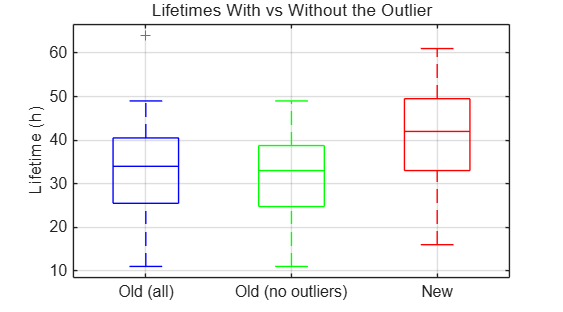

% ---- updated boxplots ----
figure('Position',[100 100 900 500]);
boxplot([old_h'; old_h_clean'; new_h'], ...
    [repmat({'Old (all)'}, old_n, 1); repmat({'Old (no outliers)'}, old_n_clean, 1); repmat({'New'}, new_n, 1)], ...
    'Colors', ['b','g','r']);
title('Lifetimes With vs Without the Outlier');
ylabel('Lifetime (h)');
grid on;

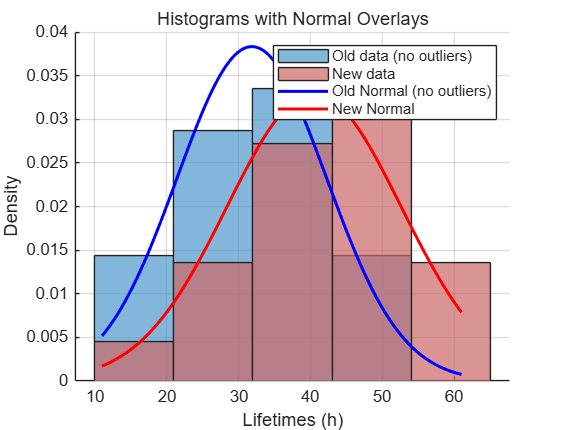


% ---- updated histograms ----
figure('Color','w','Position',[100 100 980 750]); hold on;
k_clean = round(1 + 3.322 * log10(old_n_clean));
[observed_freq, edges_clean] = histcounts([old_h_clean new_h], k_clean);

histogram(old_h_clean, 'BinEdges', edges_clean, 'Normalization','pdf', 'FaceColor',[0.3 0.6 0.8], 'FaceAlpha',0.7);
histogram(new_h, 'BinEdges', edges_clean, 'Normalization','pdf', 'FaceColor',[0.8 0.4 0.4], 'FaceAlpha',0.7);
x = linspace(min([old_h_clean new_h]), max([old_h_clean new_h]), 300);
plot(x, normpdf(x, old_mean_clean, old_std_clean), 'b-', 'LineWidth', 1.8);
plot(x, normpdf(x, new_mean, new_std), 'r-', 'LineWidth', 1.8);
title('Histograms with Normal Overlays');
xlabel('Lifetimes (h)'); ylabel('Density');
legend('Old data (no outliers)','New data','Old Normal (no outliers)','New Normal','Location','northeast');
grid on; hold off;

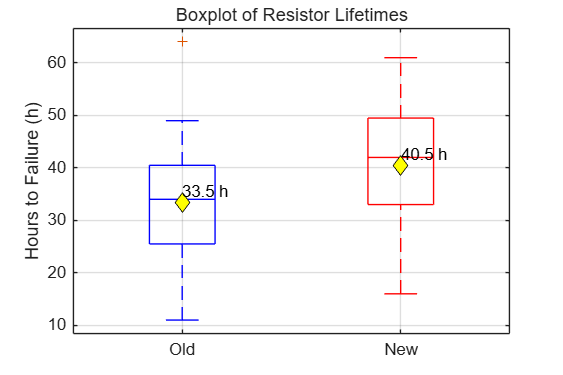

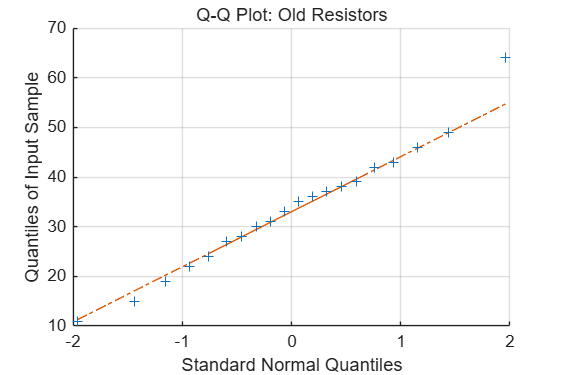

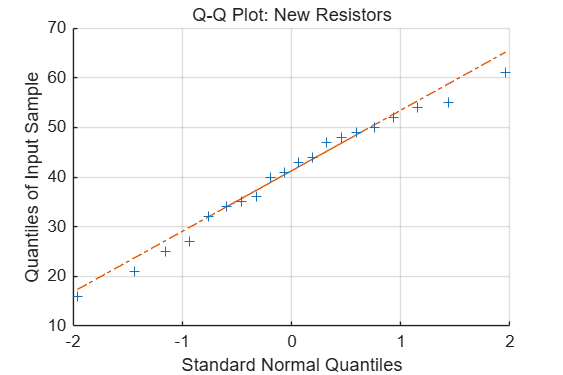

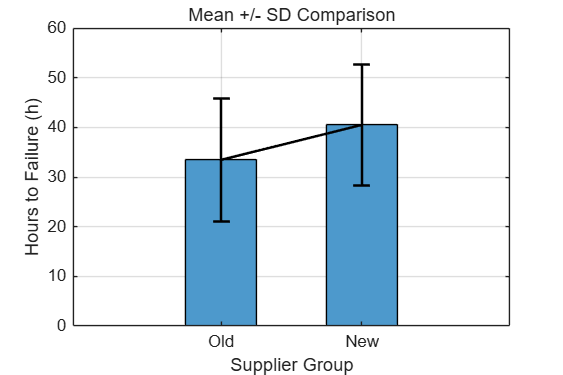

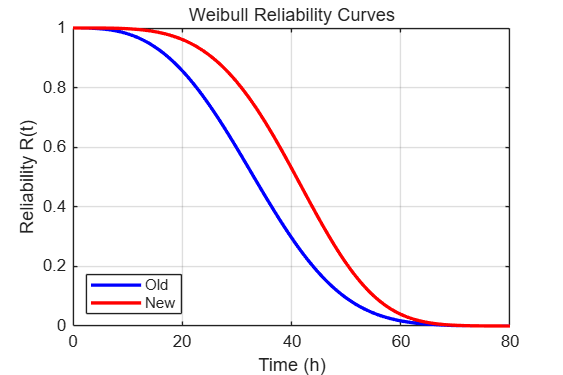

% ==========================================================
% Visualisation : Complete Analysis (Advanced)
% Includes: Annotated Boxplot, IQR Outlier Bounds, Q-Q plots, 
% Mean +/- SD, Weibull Curves, and Paired Difference (D) Analysis
% ==========================================================

% Ensure D exists (calculate if it wasn't defined by teammates)
D = new_h - old_h; 

% ----------------------------------------------------------
% 1. Basic Annotated Boxplot (Lecturer's Template)
% ----------------------------------------------------------
figure('Color','w','Position',[100 100 600 400]);
boxplot([old_h'; new_h'], [repmat({'Old'}, old_n, 1); repmat({'New'}, new_n, 1)], 'Colors', ['b','r']);
title('Boxplot of Resistor Lifetimes');
ylabel('Hours to Failure (h)');
hold on;
plot(1:2, [old_mean, new_mean], 'kd', 'MarkerFaceColor', 'y', 'MarkerSize', 8);
text(1:2, [old_mean, new_mean] + 2, compose('%.1f h', [old_mean, new_mean]), 'Color', 'k');
grid on; 
hold off;

% ----------------------------------------------------------
% 2. [New] Horizontal Boxplot with IQR Bounds (Outlier Criteria)
% ----------------------------------------------------------
figure('Color','w','Position',[100 100 700 400]);
boxplot(old_h, 'Orientation','horizontal', 'Colors', 'b'); 
hold on;
% Calculate IQR bounds
Q1 = quantile(old_h, 0.25); Q3 = quantile(old_h, 0.75); IQR_val = Q3 - Q1;
lb = Q1 - 1.5 * IQR_val; ub = Q3 + 1.5 * IQR_val;

% Draw bound lines
xline(lb, 'r--', sprintf('Lower Bound (%.1f)', lb), 'LineWidth', 1.5, 'LabelVerticalAlignment', 'bottom');
xline(ub, 'r--', sprintf('Upper Bound (%.1f)', ub), 'LineWidth', 1.5, 'LabelVerticalAlignment', 'bottom');

% Highlight the 64h outlier
text(64, 1.1, 'Outlier (64h)', 'HorizontalAlignment', 'center', 'Color', 'k', 'FontWeight', 'bold');
plot(64, 1, 'kx', 'MarkerSize', 10, 'LineWidth', 2); 

title('Old Group: Boxplot with IQR Outlier Bounds');
xlabel('Lifetime (h)');
grid on;
hold off;

% ----------------------------------------------------------
% 3. Q-Q Plots for Normality Validation
% ----------------------------------------------------------
figure('Color','w','Position',[100 100 600 400]);
qqplot(old_h);
title('Q-Q Plot: Old Resistors');
xlabel('Standard Normal Quantiles');
ylabel('Quantiles of Input Sample');
grid on;

figure('Color','w','Position',[100 100 600 400]);
qqplot(new_h);
title('Q-Q Plot: New Resistors');
xlabel('Standard Normal Quantiles');
ylabel('Quantiles of Input Sample');
grid on;

% ----------------------------------------------------------
% 4. Mean +/- SD Bar Chart
% ----------------------------------------------------------
figure('Color','w','Position',[100 100 600 400]);
bar([old_mean, new_mean], 0.5, 'FaceColor',[0.3 0.6 0.8], 'EdgeColor', 'k');
hold on;
errorbar(1:2, [old_mean, new_mean], [old_std, new_std], 'k', 'LineWidth', 1.5, 'CapSize', 10);
set(gca, 'XTickLabel', {'Old', 'New'});
title('Mean +/- SD Comparison');
xlabel('Supplier Group');
ylabel('Hours to Failure (h)');
grid on;
hold off;

% ----------------------------------------------------------
% 5. Weibull Reliability Curves (Fixed)
% ----------------------------------------------------------
figure('Color','w','Position',[100 100 600 400]);
t = linspace(0, 80, 200);
old_pd = fitdist(old_h', 'Weibull');
new_pd = fitdist(new_h', 'Weibull');
R_old = 1 - cdf(old_pd, t);
R_new = 1 - cdf(new_pd, t);

plot(t, R_old, 'b-', 'LineWidth', 2);
hold on;
plot(t, R_new, 'r-', 'LineWidth', 2);
title('Weibull Reliability Curves');
xlabel('Time (h)');
ylabel('Reliability R(t)');
legend('Old', 'New', 'Location', 'southwest');
grid on;

val_old_40 = interp1(t, R_old, 40) * 100;
val_new_40 = interp1(t, R_new, 40) * 100;

summary_str = {
    '\bfReliability Insight';
    sprintf('At t=40h:');
    sprintf('Old: %.1f%%', val_old_40);
    sprintf('New: %.1f%%', val_new_40);
    };

text(5, 0.4, summary_str, 'FontSize', 11, 'BackgroundColor', 'w', 'EdgeColor', 'k', 'Margin', 5);
hold off;

% ----------------------------------------------------------
% 6. [New] Paired Differences (D) Dual Analysis (Great for Presentation)
% ----------------------------------------------------------
figure('Color','w','Position',[100 100 1000 400]);
t_layout = tiledlayout(1,2, 'TileSpacing','compact', 'Padding','compact');

% Left subplot: Histogram of differences
nexttile;
histogram(D, 10, 'FaceColor', [0.3 0.6 0.8], 'EdgeColor', 'k');
hold on;
yline(mean(D), 'r--', 'LineWidth', 2); 
text(mean(D)+1, 3, sprintf('Mean Diff = %.1f h', mean(D)), 'Color', 'r', 'FontWeight', 'bold');
xlabel('Difference (New - Old) in hours'); 
ylabel('Count');
title('Distribution of Paired Differences');
grid on;

% Right subplot: Scatter plot of differences
nexttile;
plot(1:20, D, 'bo-', 'LineWidth', 1.5, 'MarkerFaceColor', 'b');
hold on;
yline(0, 'k-', 'LineWidth', 1.5); 
yline(mean(D), 'r--', 'LineWidth', 1.5); 
xlabel('Pair ID'); 
ylabel('New - Old (hours)');
title('Paired Differences by Pair');
grid on;

sgtitle('Paired Differences Analysis: New vs Old', 'FontSize', 14, 'FontWeight', 'bold');